## Define data

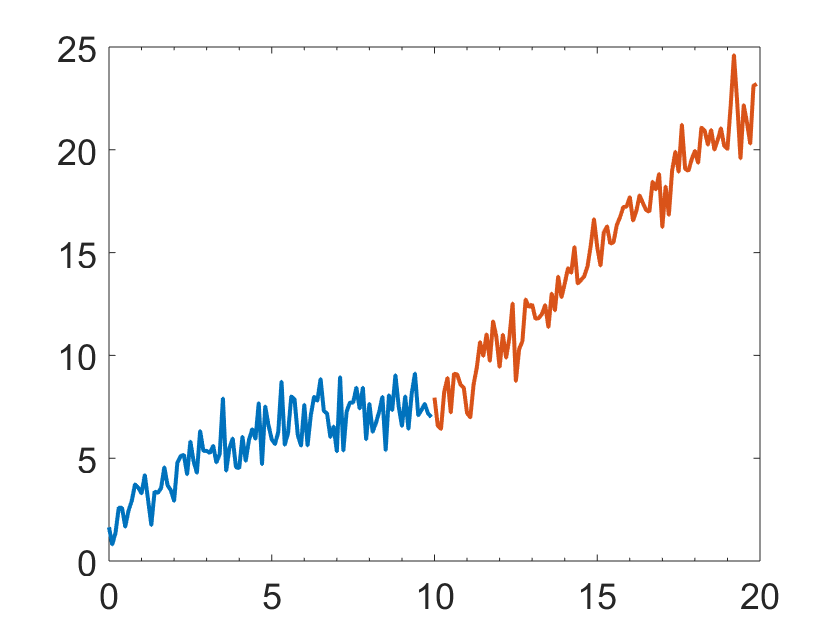

sample = 100;
  x1 = linspace(0,9.9); y1= 1 + 1.6 * x1 - 0.1.*x1.^2; 
  x2 = linspace(10,19.9); y2= 1.6 * x2 - 9; 
  x = [x1,x2]; y = [y1+r(1,:),y2+r(2,:)];
  r = randn(2,sample); 
    figure
    plot(x1,r(1,:)+y1) 
    hold on
    plot(x2,r(2,:)+y2)

fcall = @(x,a,b) a + b.*x;

fcall = function_handle with value:
    @(x,a,b)a+b.*x


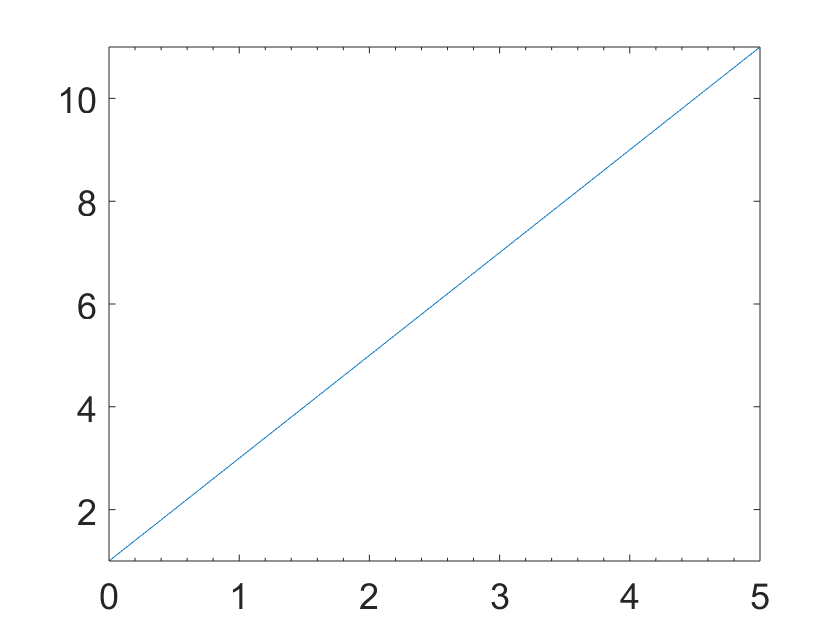

fplot(@(x)fcall(x,1,2),[0 5])

## Define fit

% x1 = [0.81;0.91;0.13;0.91;0.63;0.098;0.28;0.55;0.96;0.96;0.16;0.97;0.96];
% y1 = [0.17;0.12;0.16;0.0035;0.37;0.082;0.34;0.56;0.15;-0.046;0.17;-0.091;-0.071];
% ft = fittype( 'piecewiseLine( x, a, b, c, d, k )','independent', 'x', 'dependent', 'y' )
% ft = fittype( 'a + b.*x','independent', 'x', 'dependent', 'y' )
ft = fittype(@(a,b,c,d,x)test(x,a,b,c,d,8,12),'independent', 'x', 'dependent', 'y' )

ft =      General model:
     ft(a,b,c,d,x) = test(x,a,b,c,d,8,12)

f = fit(x', y', ft, 'StartPoint', [0,1,0,1] )

f =      General model:
     f(x) = test(x,a,b,c,d,8,12)
     Coefficients (with 95% confidence bounds):
       a =      0.7572  (-0.5851, 2.1)
       b =       1.608  (1.259, 1.956)
       c =    -0.09297  (-0.1534, -0.03259)
       d =      -9.178  (-14.8, -3.556)

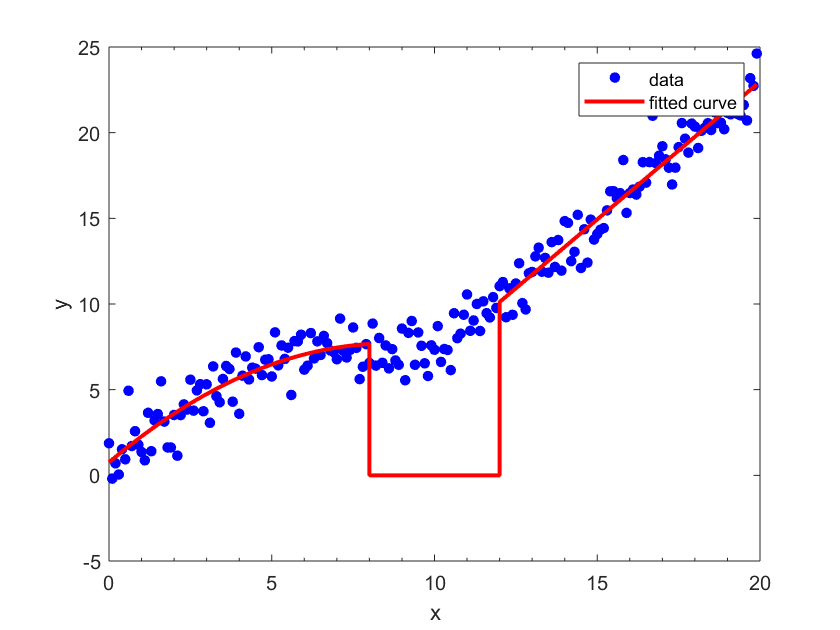

figure
plot( f, x, y ) 

## Functions

function y = testcall(x,a,b)
    y = a + b.*x;
end

function y=test(x,a,b,c,d,xl1,xl2)
    y = zeros(size(x));
    y(x<xl1) = a + b.*x(x<xl1) + c.*x(x<xl1).^2;
    y(x>=xl2) = testcall(x(x>=xl2),d,b);
end